# Cvičení 3 - B2M31AEDA

## Nahrání dat

Dejte si pozor na to, aby jste byli v MATLABu ve složce, kde máte umístěn soubor s daty (data.csv), nebo máte složku, ve které je soubor s daty, přidanou do cesty MATLABu (Matlab Path).

T = readtable('data.csv','ReadVariableNames',true);

Prohlédněte si data - hodnoty a jejich popisky - přístupem ke sloupcům v tabulce:

D = T.VOT; % Hodnoty - data
L = T.subject; % Popisky - labels
G = T.group;

## 1. Vizualizace a výpočet Cohenova d

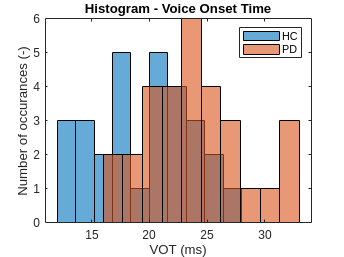

% Váš kód pro vizualizaci
DHC = D(string(G)=='HC'); DPD = D(string(G)=='PD');
nHC = length(DHC); nPD = length(DPD);
muHC = mean(DHC); muPD = mean(DPD);
sHC = std(DHC); sPD = std(DPD);

histogram(DHC, 10);
hold on
histogram(DPD, 10);
hold off

title("Histogram - Voice Onset Time");
xlabel("VOT (ms)"); ylabel("Number of occurances (-)");
legend("HC", "PD")

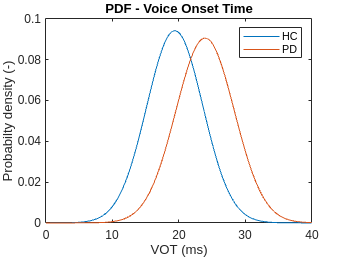


x = linspace(0, 40, 1000);
pdfHC = normpdf(x, muHC, sHC);
pdfPD = normpdf(x, muPD, sPD);

plot(x, pdfHC);
hold on
plot(x, pdfPD);
hold off
title("PDF - Voice Onset Time");
xlabel("VOT (ms)"); ylabel("Probabilty density (-)");
legend("HC", "PD")

**Otázky:**

- *Jak byste pouhým okem zhodnotili efekt skupin, tj. rozdíly mezi skupinami, viditelné na vaší vizualizaci?*

skupina PD má mediánově pomalejší VOT

% Váš kód pro výpočet Cohenova d

sP = sqrt(((nHC - 1)*(sHC^2) + (nPD - 1)*(sPD^2))/(nHC+nPD+2));
d = (muHC - muPD)/sP

d = -1.0906

**Otázky:**

- *Jaký silný je efekt mezi analyzovanými skupinami?*

d je větší jak 1, tedy efekt je velký

## 2. Odhad parametrů normálního rozložení a výpočet populační CDF

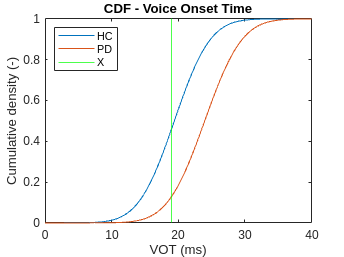

% Váš kód
% Nápověda: Populační CDF je hladký, Empirický CDF graf má tvar schodů.
cdfHC = cdf("Normal",x,muHC,sHC);
cdfPD = cdf("Normal",x,muPD,sPD);

plot(x,cdfHC)
hold on
plot(x,cdfPD)
xline(D(string(L)=="X"), Color="green")
hold off
title("CDF - Voice Onset Time");
xlabel("VOT (ms)"); ylabel("Cumulative density (-)");
legend("HC", "PD", "X", "Location","northwest")

**Otázky:**

- *Přiřadili byste subjekt X spíše do skupiny HC, do skupiny PD nebo byste ho nezařadili do ani do jedné?*

*Přiřadil bych spíše k HC*

DHC = [DHC;D(string(L)=="X")];
nHC = length(DHC);
muHC = mean(DHC);
sHC = std(DHC);

## 3. Bootstrapping

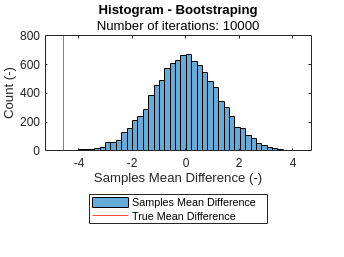

% Váš kód pro bootstrapping
tmd = muHC-muPD;
alpha = 0.05;

noiter = 10e03;

x = zeros([noiter, nHC]);
y = zeros([noiter, nPD]);

n = length(D);

for i=1:noiter
    x(i,:) = D(randi(n, 1, nHC));
    y(i,:) = D(randi(n, 1, nPD));
end

smd = mean(x,2)-mean(y,2);

histogram(smd, 45);
hold on
xline(tmd, Color="red")
hold off
title("Histogram - Bootstraping");
subtitle(sprintf("Number of iterations: %i", noiter))
xlabel("Samples Mean Difference (-)"); ylabel("Count (-)");
legend("Samples Mean Difference", "True Mean Difference", "Location","southoutside")

% Váš kód pro t-test
% Nápověda: ttest2()
pval = sum(abs(tmd) <= abs(smd))/noiter;
hval = pval <= alpha;

[h, p, c, stats] = ttest2(DHC,DPD, "Alpha",alpha)

h = 1

p = 1.1735e-04

c =    -6.7854
   -2.3561


stats = struct with fields:
    tstat: -4.1312
       df: 58
       sd: 4.2850


- **Slovní znění vašich hypotéz, vaše nastavení hladiny statistické významnosti a vypočtená hodnota *****p*****-value z bootstrappingu.**

H0: Skupina HC i skupina PD mají stejnou střední hodnotu

alpha = 5%

p-value je 0.02%

- **Korektní report výsledku t-testu. **

t(58) =-4.1312, p=1.17e-04

- **Velmi stručná interpretace výsledků.**

p-value je menší, než alpha, tedy hypotézu H0 zamítáme ve prospěch alternativní hypotézy. Tzn střední hodnoty rozdělení dat obou skupin nejsou stejné

- **Porovnání výsledků bootstrappingu s výsledky funkce ttest2.**

Bootstraping je náhodný, vychází v rozmezí p=1e-04 až 4e-04. Naopak ttest2 pracuje pouze s původními daty, tedy jeho výsledek je vždy stejný, avšak snadno ovlivnitelný novým outlierem.

## Nepovinný bonus

% Váš kód
% Nápověda: Bayesova věta
DHC = D(string(G)=='HC'); DPD = D(string(G)=='PD');
nHC = length(DHC); nPD = length(DPD);
muHC = mean(DHC); muPD = mean(DPD);
sHC = std(DHC); sPD = std(DPD);

X = D(string(L)=="X");

PPD = 0.3/100;
PHC = 1-PPD;

fHC = normpdf(X, muHC, sHC);
fPD = normpdf(X, muPD, sPD);

K = PHC/PPD * fHC/fPD;

if K > 1
    fprintf("Vzorek X patří do skupiny HC");
else
    fprintf("Vzorek X patří do skupiny PD");
end

Vzorek X patří do skupiny HC